%% Load feature data
clear; clc;
load("results/ml/philharmonia_features.mat");

fprintf("Loaded %d samples, feature dim = %d\n", size(X,1), size(X,2));

Loaded 4169 samples, feature dim = 30


uniqueLabels = unique(Labels);
fprintf("Detected %d instruments:\n", numel(uniqueLabels));

Detected 7 instruments:


disp(uniqueLabels);

    "bassoon"
    "cello"
    "flute"
    "guitar"
    "oboe"
    "trombone"
    "tuba"



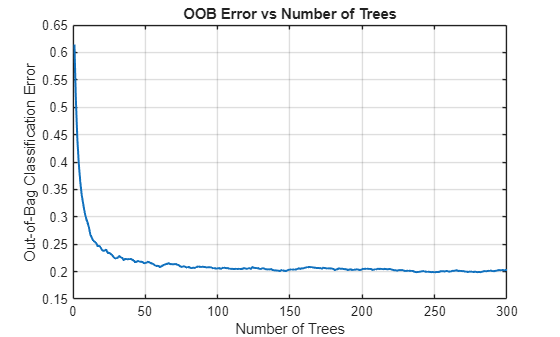

% ============ 1) 分层划分 + 标准化 ============
rng(42);                               % 固定随机种子，结果可复现
Y = categorical(Labels);               % 统一标签
cv = cvpartition(Y,'Holdout',0.2);     % 分层划分（每类都按比例进测试集）

Xtrain = X(training(cv),:);
Ytrain = Y(training(cv));
Xtest  = X(test(cv),:);
Ytest  = Y(test(cv));

mu = mean(Xtrain,1);
sigma = std(Xtrain,[],1);
Xtrain = (Xtrain - mu) ./ (sigma + 1e-6);
Xtest  = (Xtest  - mu) ./ (sigma + 1e-6);

% ============ 2) 随机森林（带 OOB 曲线） ============
MdlRF = TreeBagger(300, Xtrain, Ytrain, ...
    'Method','classification', ...
    'OOBPrediction','On', ...
    'OOBPredictorImportance','On', ...
    'MinLeafSize',5, ...
    'NumPredictorsToSample','all', ...
    'SampleWithReplacement','on');

figure; plot(oobError(MdlRF),'LineWidth',1.5); grid on;
xlabel('Number of Trees'); ylabel('Out-of-Bag Classification Error');
title('OOB Error vs Number of Trees');


% ============ 3) SVM（更稳默认：自动尺度 + 较强 Box） ============
tpl = templateSVM('KernelFunction','rbf','KernelScale','auto','BoxConstraint',8);
MdlSVM = fitcecoc(Xtrain, Ytrain, 'Coding','onevsone', 'Learners', tpl);

% ============ 3b) 再加两个基线模型 ============
MdlKNN = fitcknn(Xtrain, Ytrain, 'NumNeighbors', 5, 'Distance','cosine');     % kNN
MdlNB  = fitcnb( Xtrain, Ytrain, 'DistributionNames','kernel');               % 朴素贝叶斯


% ============ 4) 四模型统一对比，自动选最好 ============

% 统一类别顺序，避免预测类型不一致
ord = categories(Y);

% 用本地函数做安全预测（见文末 local_predict_cat）
predict_cat = @(mdl,X) local_predict_cat(mdl, X, ord);

% 逐个预测
Yhat_RF  = predict_cat(MdlRF,  Xtest);
Yhat_SVM = predict_cat(MdlSVM, Xtest);
Yhat_KNN = predict_cat(MdlKNN, Xtest);
Yhat_NB  = predict_cat(MdlNB,  Xtest);

% 计算准确率
acc_RF  = mean(Yhat_RF  == categorical(Ytest,ord));
acc_SVM = mean(Yhat_SVM == categorical(Ytest,ord));
acc_KNN = mean(Yhat_KNN == categorical(Ytest,ord));
acc_NB  = mean(Yhat_NB  == categorical(Ytest,ord));

fprintf('RF Acc  = %.2f%% | SVM Acc = %.2f%% | kNN Acc = %.2f%% | NB Acc = %.2f%%\n', ...
        acc_RF*100, acc_SVM*100, acc_KNN*100, acc_NB*100);

RF Acc  = 81.63% | SVM Acc = 87.88% | kNN Acc = 83.19% | NB Acc = 64.95%



% 组成一个列表，选最优
names = ["Random Forest","SVM (RBF)","kNN","Naive Bayes"];
accs  = [acc_RF, acc_SVM, acc_KNN, acc_NB];
yhats = {Yhat_RF,  Yhat_SVM, Yhat_KNN, Yhat_NB};
mdls  = {MdlRF,    MdlSVM,   MdlKNN,   MdlNB};

[bestAcc, idx] = max(accs);
bestName = names(idx);
Ypred    = yhats{idx};
Mdl      = mdls{idx};

fprintf('✅ Using model: %s | Test Acc = %.2f%%\n', bestName, bestAcc*100);

✅ Using model: SVM (RBF) | Test Acc = 87.88%



% ============ 5) 更全面的评估：confusion + per-class F1 ============
order = categories(Y);    % 固定类别顺序，避免空类缺失
[C, order] = confusionmat(categorical(Ytest,order), categorical(Ypred,order));

prec = diag(C) ./ max(1, sum(C,1))';   % precision：按列
rec  = diag(C) ./ max(1, sum(C,2));    % recall：按行
f1   = 2*prec.*rec ./ max(1e-12,prec+rec);
macroF1 = mean(f1);

fprintf('Overall Accuracy: %.2f%% | Macro-F1: %.2f%%\n', ...
        mean(Ypred==Ytest)*100, macroF1*100);

Overall Accuracy: 87.88% | Macro-F1: 87.05%


disp(table(order,prec,rec,f1,'VariableNames',{'Class','Precision','Recall','F1'}));

     Class      Precision    Recall       F1   
    ________    _________    _______    _______

    bassoon      0.89744     0.79545    0.84337
    cello        0.86842       0.792    0.82845
    flute         0.8253     0.90728    0.86435
    guitar             1     0.77273    0.87179
    oboe             0.9     0.82759    0.86228
    trombone        0.85     0.92169    0.88439
    tuba         0.92929     0.94845    0.93878



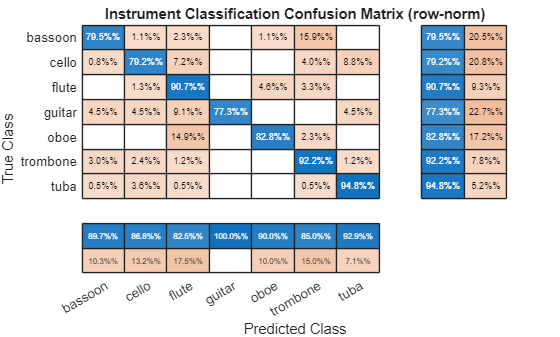


figure;
cm = confusionchart(categorical(Ytest,order), categorical(Ypred,order), ...
    'Normalization','row-normalized');
cm.CellLabelFormat = '%.1f%%';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.Title = "Instrument Classification Confusion Matrix (row-norm)";

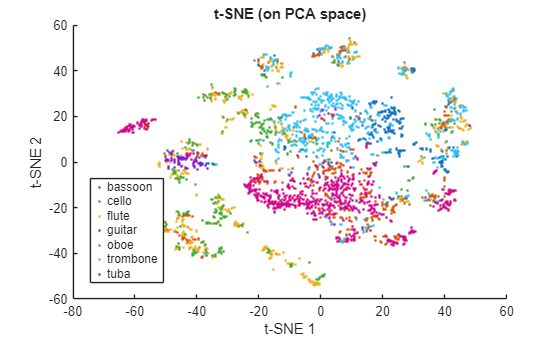


% ============ 6) t-SNE（先 PCA 再降维，更稳更快） ============
[coeff,score,~,~,expl] = pca(Xtrain);
k = find(cumsum(expl)>95,1);         % 保留 95% 方差
Z = tsne(score(:,1:k),'Perplexity',30,'Standardize',true);
figure; gscatter(Z(:,1),Z(:,2),Ytrain);
title('t-SNE (on PCA space)'); xlabel('t-SNE 1'); ylabel('t-SNE 2');


% ============ 7) 保存模型 ============
uniqueLabels = categories(Y);
save("results/ml/instrument_classifier.mat", "Mdl", "mu", "sigma", "uniqueLabels");
disp("Model saved -> results/ml/instrument_classifier.mat");

Model saved -> results/ml/instrument_classifier.mat



function ycat = local_predict_cat(mdl, X, ord)
% 统一把不同模型的 predict 输出转成 categorical
    y = predict(mdl, X);
    ycat = local_toCat(y, ord);
end

function ycat = local_toCat(y, ord)
% 把 cell/char/string/categorical 统一为 categorical，且按指定顺序 ord
    if iscategorical(y)
        ycat = categorical(y, ord);
    elseif iscell(y)
        ycat = categorical(string(y), ord);
    elseif isstring(y)
        ycat = categorical(y, ord);
    elseif ischar(y)
        ycat = categorical(string(y), ord);
    else
        % 数值/逻辑等其它情况，兜底转字符串
        ycat = categorical(string(y), ord);
    end
end


